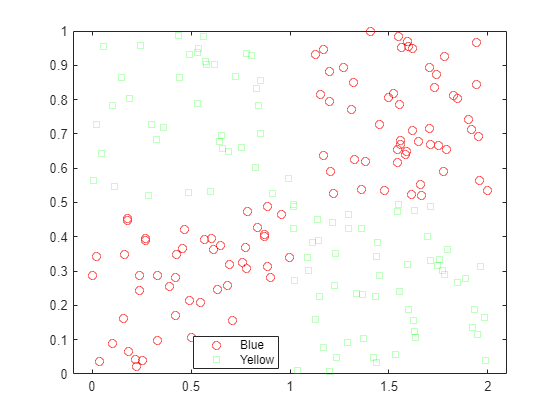

clear all
close all

numSamples = 200;
[X,Y] = generateData(numSamples);
classNames = ["Blue", "Yellow"];

gscatter(X(:,1), X(:,2), Y,'rgb','osd');

inputSize = size(X,2);
numClasses = numel(classNames);


% % % load fisheriris
% % % rng(1);
% % % % f = figure;
% % % % gscatter(meas(:,1), meas(:,2), species,'rgb','osd');
% % % % xlabel('Sepal length');
% % % % ylabel('Sepal width');
% % % % 
% % % X = meas(:,1:4);
% % % Y = [];%zeros(150,1);
% % % for i=1:150
% % %     y = species{i};
% % %     Y=[Y string(y)];
% % % end
% % % Y = categorical(Y);
% % % 
% % % inputSize = size(meas,2);
% % % numClasses = 3;
% % % numSamples = size(meas,1);

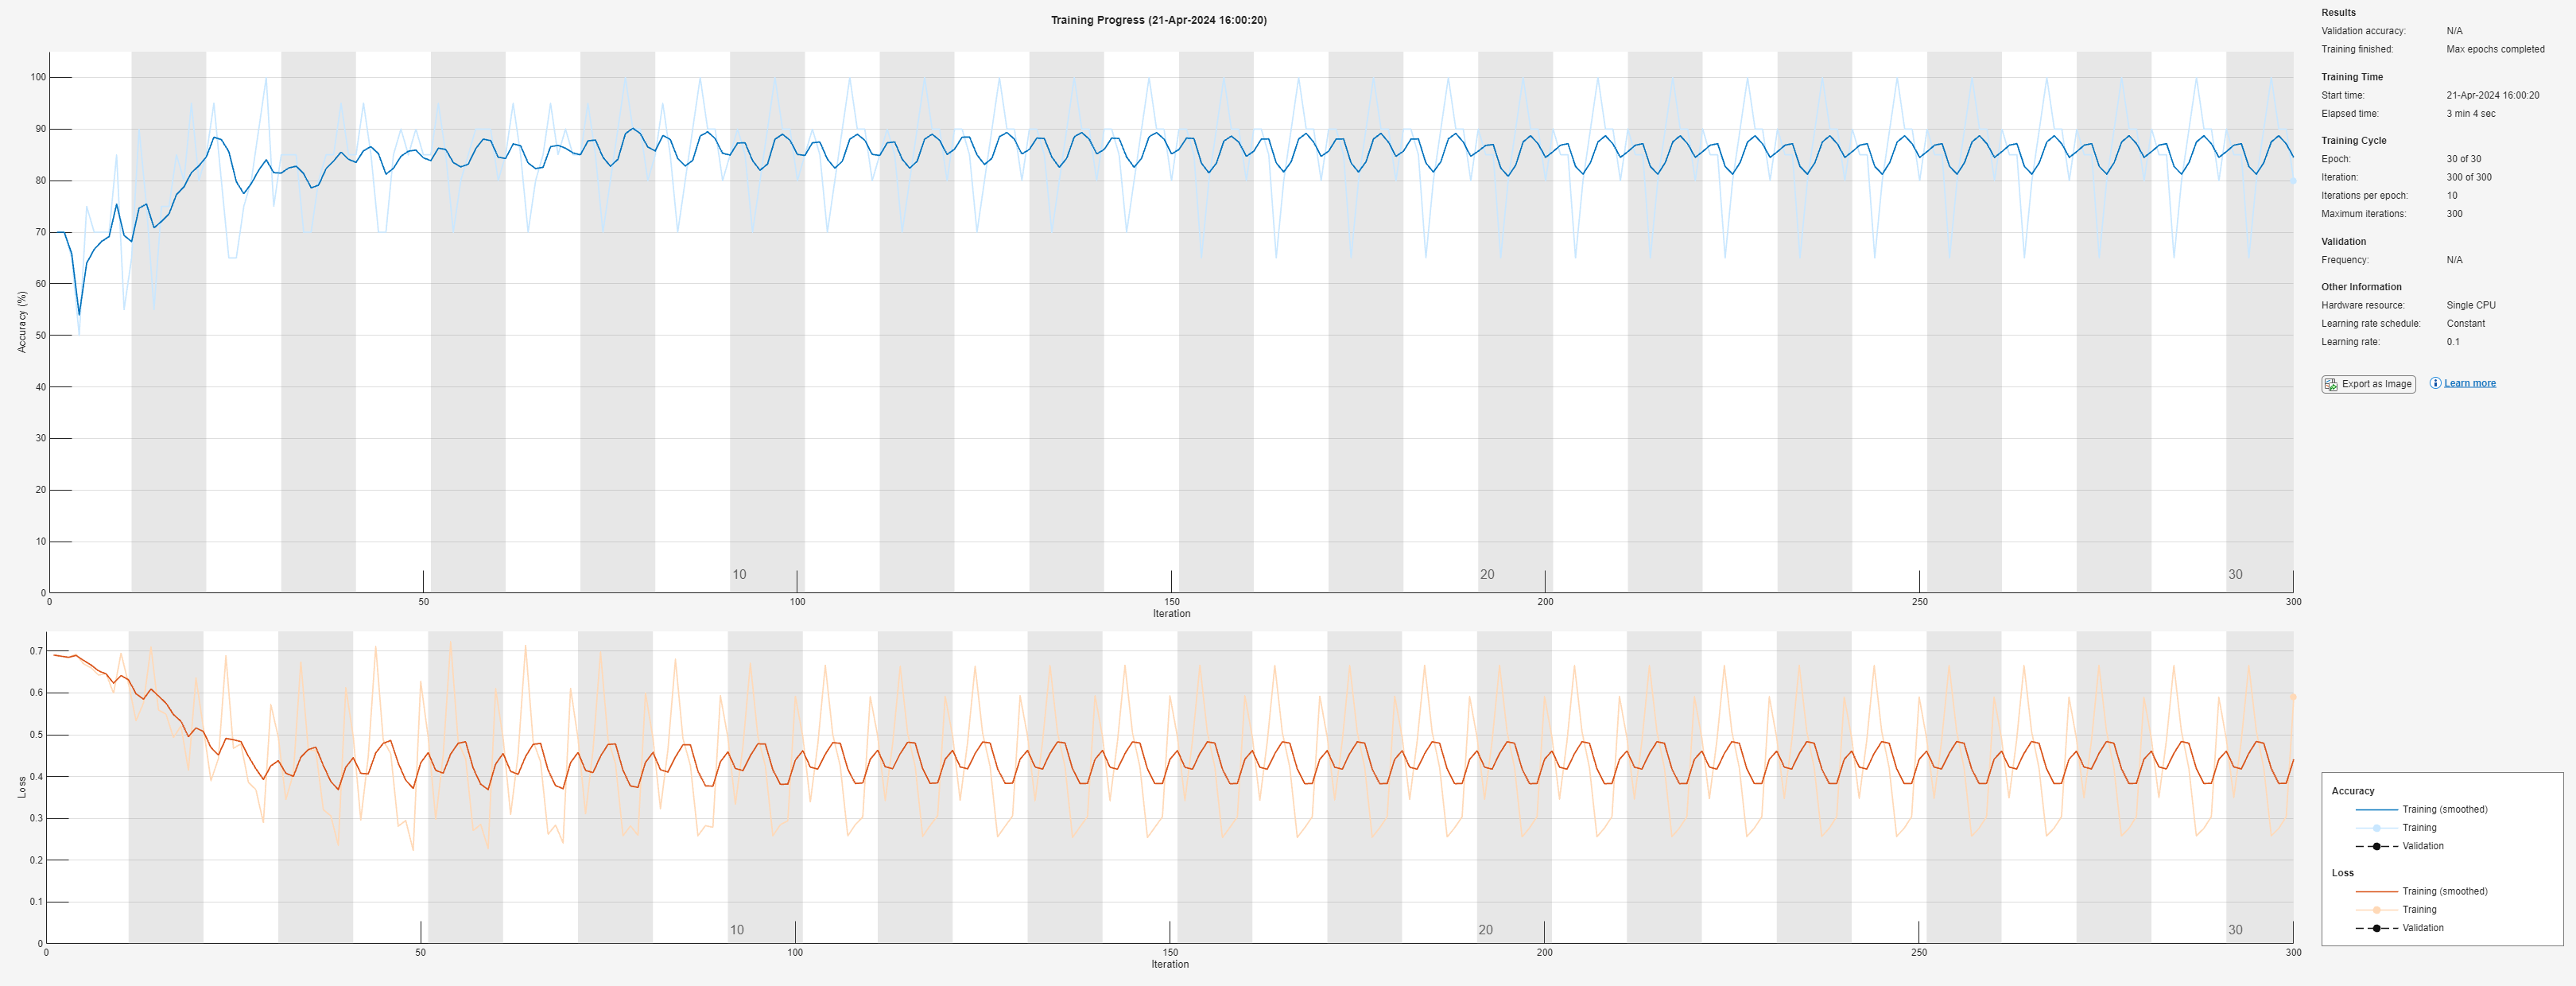

net =   SeriesNetwork with properties:

         Layers: [5×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'classoutput'}


layers = [
    featureInputLayer(inputSize,Normalization="none")
    PQCLayer2
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];


options = trainingOptions("sgdm", ...
    MiniBatchSize=20, ...
    InitialLearnRate=0.1, ...
    Momentum=0.9, ...
    ExecutionEnvironment="cpu", ...
    Plots="training-progress", ...
    Verbose=false);

net = trainNetwork(X,Y,layers,options)

## Test

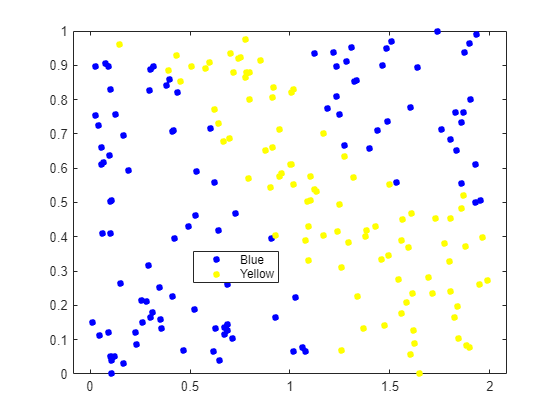

[XTest,trueLabels] = generateData(numSamples);
predictedLabels = classify(net,XTest);
gscatter(XTest(:,1),XTest(:,2),predictedLabels,"by")

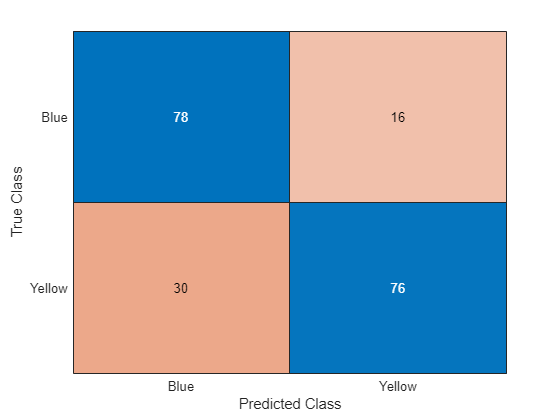

confusionchart(trueLabels,predictedLabels)

## Helper function

function [X,Y] = generateData(numSamples)
    X = zeros(numSamples,2);
    labels = strings(numSamples,1);
    for i = 1:numSamples
        x1 = 2*rand;
        x2 = rand;
        X(i,:) = [x1 x2];
        if (x1 > 1 && x2 > 0.5) || (x1 < 1 && x2 < 0.5)    
            labels(i) = "Blue";
        else
            labels(i) = "Yellow";
        end
    end
    Y = categorical(labels);
end